# Capacity Factor

Description: This algorithm check and plot data for production for the different years. Production grouped as 50 kW, 100 kW arrays and the complete power plant (950 kW)

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 10/2021

clc
clear
close all

load Y2019.mat
load Y2020.mat
load Y2021.mat

% Nominal capacity
Nom_Cap=[100.8 100.8 100.8 100.8 100.8 50.4 50.4 50.4 50.4 50.4 50.4 50.4 50.4 50.4 957.6]; %[kW] 

% Capacity Factor table
CF_2019=table2array(Y2019(:,2:end))./(Nom_Cap*24);
CF_2020=table2array(Y2020(:,2:end))./(Nom_Cap*24);
CF_2021=table2array(Y2021(:,2:end))./(Nom_Cap*24);

% Make Timetable
CF_2019=table2timetable([Y2019(:,1),array2table(CF_2019)]);
CF_2020=table2timetable([Y2020(:,1),array2table(CF_2020)]);
CF_2021=table2timetable([Y2021(:,1),array2table(CF_2021)]);
% Y2020=table2timetable(Y2020);
% Y2021=table2timetable(Y2021);


## Daily, Weekly, Monthly

% 2019
Daily_2019=retime(CF_2019,'daily','mean');
Weekly_2019=retime(CF_2019,'weekly','mean');
Monthly_2019=retime(CF_2019,'monthly','mean');
Year_2019= retime(CF_2019,'yearly','mean');

% 2020
Daily_2020=retime(CF_2020,'daily','mean');
Weekly_2020=retime(CF_2020,'weekly','mean');
Monthly_2020=retime(CF_2020,'monthly','mean');
Year_2020= retime(CF_2020,'yearly','mean');

% 2021
Daily_2021=retime(CF_2021,'daily','mean');
Weekly_2021=retime(CF_2021,'weekly','mean');
Monthly_2021=retime(CF_2021,'monthly','mean');
Year_2021= retime(CF_2021,'yearly','mean');

## Figures

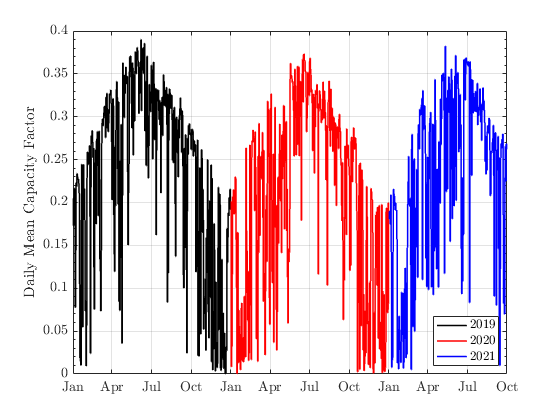

figure
stairs(Daily_2019.VarName1,Daily_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Daily_2020.VarName1,Daily_2020.CF_202015,'r','LineWidth',1.5)
stairs(Daily_2021.VarName1,Daily_2021.CF_202115,'b','LineWidth',1.5)
ylabel('Daily Mean Capacity Factor','Interpreter','latex')
xlim([datetime('1-Jan-2019') datetime('30-Sep-2021')])
datetick('x','mmm')
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','SE','interpreter','latex')

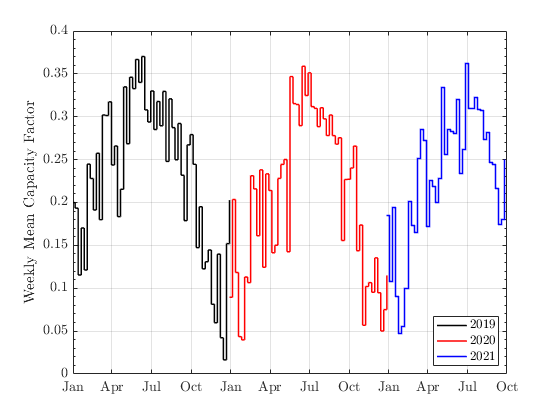


figure
stairs(Weekly_2019.VarName1,Weekly_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Weekly_2020.VarName1,Weekly_2020.CF_202015,'r','LineWidth',1.5)
stairs(Weekly_2021.VarName1,Weekly_2021.CF_202115,'b','LineWidth',1.5)
ylabel('Weekly Mean Capacity Factor','Interpreter','latex')
xlim([datetime('1-Jan-2019') datetime('30-Sep-2021')])
datetick('x','mmm')
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','SE','interpreter','latex')

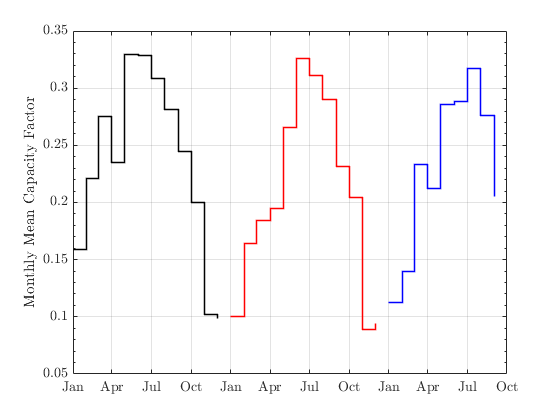


figure
stairs(Monthly_2019.VarName1,Monthly_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Monthly_2020.VarName1,Monthly_2020.CF_202015,'r','LineWidth',1.5)
stairs(Monthly_2021.VarName1,Monthly_2021.CF_202115,'b','LineWidth',1.5)
ylabel('Monthly Mean Capacity Factor','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Jan-2019') datetime('30-Sep-2021')])
datetick('x','mmm')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

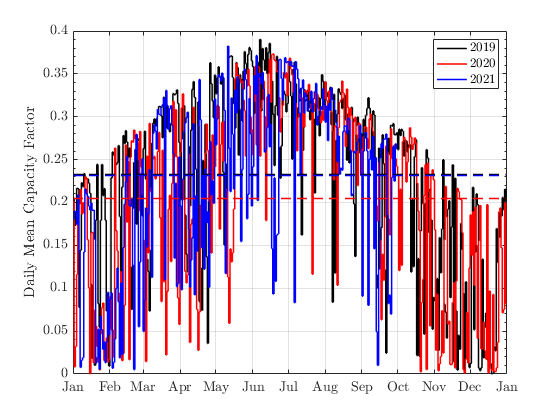

figure
stairs(Daily_2019.VarName1,Daily_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Daily_2019.VarName1,Daily_2020.CF_202015([1:59 61:end]),'r','LineWidth',1.5)
stairs(Daily_2019.VarName1(1:273),Daily_2021.CF_202115,'b','LineWidth',1.5)

stairs(Daily_2019.VarName1([1 end]),[Year_2019.CF_201915 Year_2019.CF_201915],'--k','LineWidth',1.5)
stairs(Daily_2019.VarName1([1 end]),[Year_2020.CF_202015 Year_2020.CF_202015],'--r','LineWidth',1.5)
stairs(Daily_2019.VarName1([1 end]),[Year_2021.CF_202115 Year_2021.CF_202115],'--b','LineWidth',1.5)

ylabel('Daily Mean Capacity Factor','Interpreter','latex')
xlim([datetime('1-Jan-2019') datetime('31-Dec-2019')])
datetick('x','mmm')
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','NE','interpreter','latex')

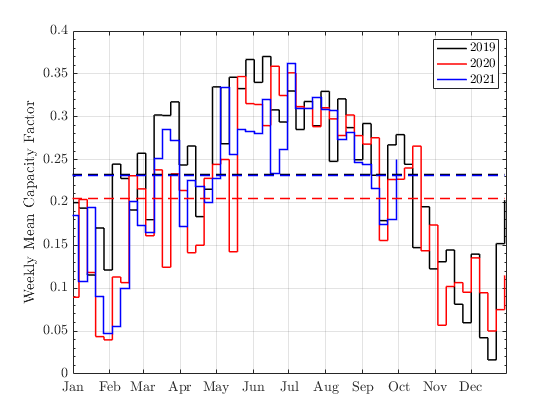

% print('-r400','-dpng','Day_Caceres.png')

figure
stairs(Weekly_2019.VarName1,Weekly_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Weekly_2019.VarName1,Weekly_2020.CF_202015,'r','LineWidth',1.5)
stairs(Weekly_2019.VarName1(1:40),Weekly_2021.CF_202115,'b','LineWidth',1.5)

stairs(Weekly_2019.VarName1([1 end]),[Year_2019.CF_201915 Year_2019.CF_201915],'--k','LineWidth',1.5)
stairs(Weekly_2019.VarName1([1 end]),[Year_2020.CF_202015 Year_2020.CF_202015],'--r','LineWidth',1.5)
stairs(Weekly_2019.VarName1([1 end]),[Year_2021.CF_202115 Year_2021.CF_202115],'--b','LineWidth',1.5)

ylabel('Weekly Mean Capacity Factor','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Jan-2019') datetime('31-Dec-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','NE','interpreter','latex')

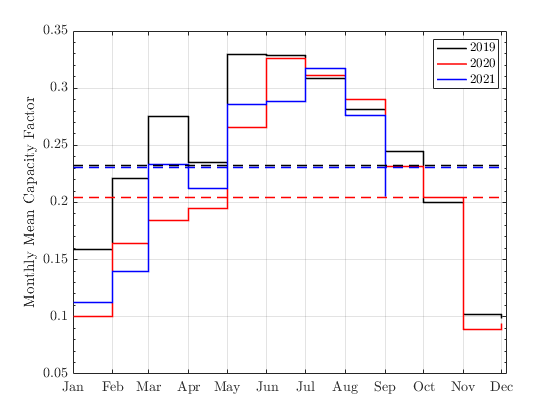

% print('-r400','-dpng','Weekly_Caceres.png')

figure
stairs(Monthly_2019.VarName1,Monthly_2019.CF_201915,'k','LineWidth',1.5)
hold on
stairs(Monthly_2019.VarName1,Monthly_2020.CF_202015,'r','LineWidth',1.5)
stairs(Monthly_2019.VarName1(1:9),Monthly_2021.CF_202115,'b','LineWidth',1.5)

stairs(Monthly_2019.VarName1([1 end]),[Year_2019.CF_201915 Year_2019.CF_201915],'--k','LineWidth',1.5)
stairs(Monthly_2019.VarName1([1 end]),[Year_2020.CF_202015 Year_2020.CF_202015],'--r','LineWidth',1.5)
stairs(Monthly_2019.VarName1([1 end]),[Year_2021.CF_202115 Year_2021.CF_202115],'--b','LineWidth',1.5)
ylabel('Monthly Mean Capacity Factor','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Jan-2019') datetime('5-Dec-2019')])
% xlabel('Nominal Capacity (kW)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','NE','interpreter','latex')

% print('-r400','-dpng','Month_Caceres.png')

## Moving Mean

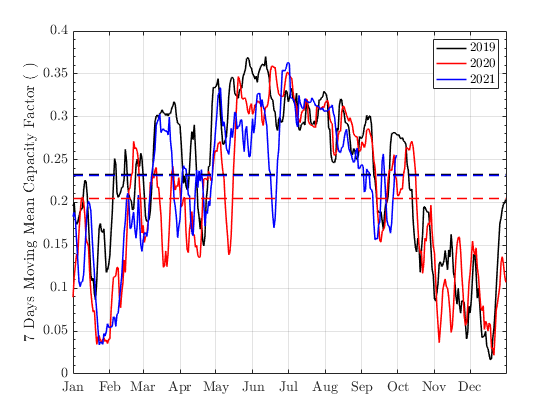

M1=movmean(Daily_2019.CF_201915,7);
M2=movmean(Daily_2020.CF_202015([1:59 61:end]),7);
M3=movmean(Daily_2021.CF_202115,7);

figure
plot(Daily_2019.VarName1,M1,'k','LineWidth',1.5)
hold on
plot(Daily_2019.VarName1,M2,'r','LineWidth',1.5)
plot(Daily_2019.VarName1(1:273),M3,'b','LineWidth',1.5)

stairs(Daily_2019.VarName1([1 end]),[Year_2019.CF_201915 Year_2019.CF_201915],'--k','LineWidth',1.5)
stairs(Daily_2019.VarName1([1 end]),[Year_2020.CF_202015 Year_2020.CF_202015],'--r','LineWidth',1.5)
stairs(Daily_2019.VarName1([1 end]),[Year_2021.CF_202115 Year_2021.CF_202115],'--b','LineWidth',1.5)

% xticks(datetime('01-Jan-2019') : calmonths(1) : datetime('31-Dec-2019'))
% xtickformat('mm')
xlim([datetime('1-Jan-2019') datetime('31-Dec-2019')])
datetick('x','mmm')
xticklabels(['Jan';'Feb';'Mar';'Apr';'May';'Jun';'Jul';'Aug';'Sep';'Oct';'Nov';'Dec'])
ylabel('7 Days Moving Mean Capacity Factor ( )','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')

set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')    
legend('2019','2020','2021','location','NE','interpreter','latex')

% print('-r400','-dpng','Mov_mean_Caceres.png')